meshsize: 16

iteration number: 1

error: 1.34235

L_infty error: 0.00178811

iteration number: 2

error: 0.31349

L_infty error: 0.00152608

iteration number: 3

error: 0.0624635

L_infty error: 0.00146605

iteration number: 4

error: 0.0131545

L_infty error: 0.00145496

iteration number: 5

error: 0.00263027

L_infty error: 0.00145274

iteration number: 6

error: 0.000526028

L_infty error: 0.0014523

iterations: 6

L_infty error: 0.0014523

active_count: 0

meshsize: 32

iteration number: 1

error: 0.820552

L_infty error: 0.000901977

iteration number: 2

error: 0.366519

L_infty error: 0.000649809

iteration number: 3

error: 0.200175

L_infty error: 0.000594414

iteration number: 4

error: 0.0705223

L_infty error: 0.000587912

iteration number: 5

error: 0.0221876

L_infty error: 0.000587835

iteration number: 6

error: 0.00494648

L_infty error: 0.000587826

iteration number: 7

error: 0.00101474

L_infty error: 0.000587828

iteration number: 8

error: 0.000202949

L_infty error: 0.000587828

iterations: 8

L_infty error: 0.000587828

active_count: 2

meshsize: 64

iteration number: 1

error: 0.688805

L_infty error: 0.000483561

iteration number: 2

error: 0.172899

L_infty error: 0.000364974

iteration number: 3

error: 0.0497447

L_infty error: 0.00034418

iteration number: 4

error: 0.0273755

L_infty error: 0.000339453

iteration number: 5

error: 0.00692504

L_infty error: 0.000338417

iteration number: 6

error: 0.00343634

L_infty error: 0.000338206

iteration number: 7

error: 0.000746533

L_infty error: 0.000338165

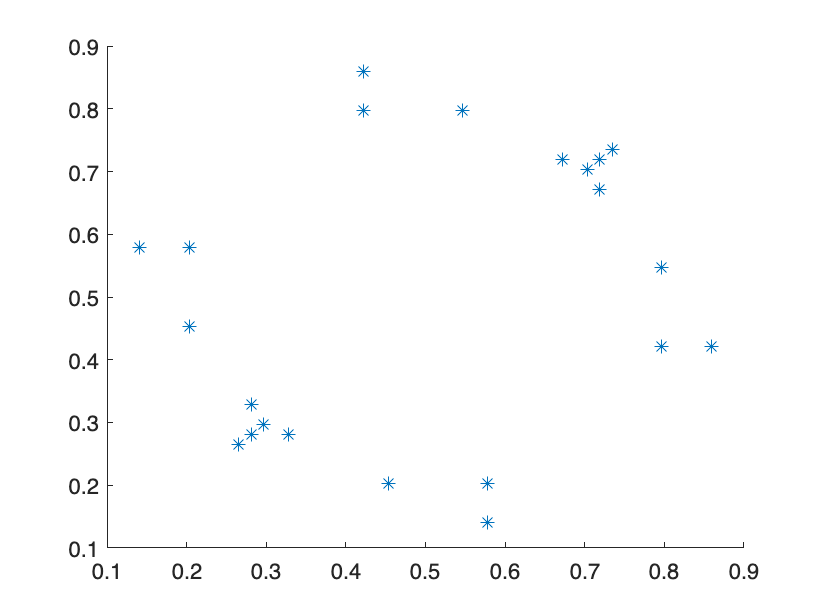

iterations: 7

L_infty error: 0.000338165

active_count: 22

meshsize: 128

iteration number: 1

error: 0.763447

L_infty error: 0.000264714

iteration number: 2

error: 0.318839

L_infty error: 0.000219643

iteration number: 3

error: 0.125418

L_infty error: 0.000202814

g = @(x,y)-sqrt(2-x.^2-y.^2);
f = @(x,y) 2*(2-x.^2-y.^2).^(-2);
g = @(x,y) exp(x.^2./2+ y.^2/2);
f = @(x,y) (1 + x.^2 +y.^2) .* exp(x.^2+y.^2);
g = @(x,y) g_C1(x,y);
f = @(x,y) f_C1(x,y);
N = 2^4;
L_infty_error=zeros(1,5);
activeset_count =zeros(1,5);
Newtonsteps=zeros(1,5);
temp=0;
for k=4:5
    fprintf('meshsize: %d',2^k);
    N=2^k;
    U0=zeros(N+1,N+1);
    h=1/N;
    for i=1:N+1
        for j=1:N+1
            U0(i,j) = g((j-1)*h,(i-1)*h);
        end
    end
    if N==2^4
        U = generate_intial_guess(f,g,2^4,N); %粗网格初值通过解Laplace方程并凸化得到
    else
        U = refine_interpolation(U,N/2,N); %后续的初值则由前面插值得到
    end
    % 参数选取
    alpha=4/5;
    beta=2/5;
    tau = 0.8;% damping
    delta = h^alpha;
    theta = h^beta;
    sigma=1e-4;
    t_filter=0.62*h^(2/5);% threshhold in F
    ite=0;
    [U,error0,active_sets,active_count]=newton_increment_filter(U,N,delta,theta,delta,theta,f,tau,t_filter,sigma);
    while 1
        [U,error,active_sets,active_count]=newton_increment_filter(U,N,delta,theta,delta,theta,f,tau,t_filter,sigma);
        ite=ite+1;
        Linfty = max(max(abs(U0-U)));
        fprintf('iteration number: %d',ite);
        fprintf('error: %g',error);
        fprintf('L_infty error: %g',Linfty);
        if error<1e-3 || Linfty<min(temp/2,0.5*1e-3) || ite>8
            temp = Linfty;
            scatter(active_sets(:,1),active_sets(:,2),50,'*');
            Filename = sprintf('discont_activesets_2^%d.jpg',k);
            saveas(gcf,Filename);
            break
        end
    end
    fprintf('**********');
    fprintf('iterations: %d',ite);
    fprintf('L_infty error: %g',Linfty);
    fprintf('active_count: %d',active_count-1);
    fprintf('**********');
end